k = 4.66;
m1 = 0.0917;
m2 = 0.0765;

A = [0 0 1 0; 0 0 0 1; (-2*k/m1) (k/m1) 0 0; (k/m2) (-k/m2) 0 0]

A =          0         0    1.0000         0
         0         0         0    1.0000
 -101.6358   50.8179         0         0
   60.9150  -60.9150         0         0


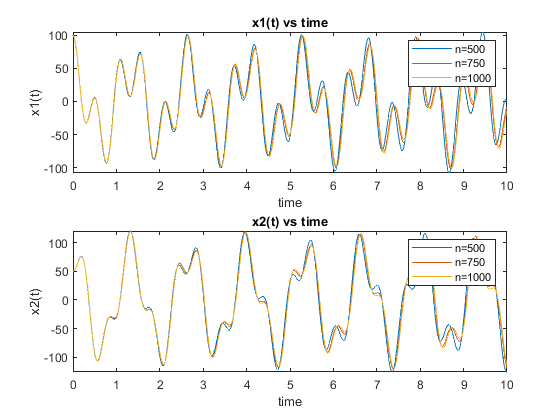

x = [100 ; 50; 0; 0];
T = 10;
N = [500,750,1000];

[x1_1,x2_1,t1] = IEMsolver(A,x,T,N(1));
[x1_2,x2_2,t2] = IEMsolver(A,x,T,N(2));
[x1_3,x2_3,t3] = IEMsolver(A,x,T,N(3));

figure

subplot1 = subplot(2,1,1);

plot(t1,x1_1);
hold on
plot(t2,x1_2);
hold on
plot(t3,x1_3);
title('x1(t) vs time')
xlabel(subplot1,'time')
ylabel(subplot1,'x1(t)')
legend('n=500','n=750','n=1000')

subplot2 = subplot(2,1,2);
plot(t1,x2_1);
hold on
plot(t2,x2_2);
hold on
plot(t3,x2_3);
title('x2(t) vs time')
xlabel(subplot2,'time')
ylabel(subplot2,'x2(t)')
legend('n=500','n=750','n=1000')


eig(A)

ans =    0.0000 +11.8542i
   0.0000 -11.8542i
  -0.0000 + 4.6935i
  -0.0000 - 4.6935i


function [x1,x2,t] = IEMsolver(A,x,T,N)
    dt = T/N;
    t = 0:dt:T;
    
    SOL = NaN(4,length(t));
    SOL(1,1) = x(1);
    SOL(2,1) = x(2);
    SOL(3,1) = x(3);
    SOL(4,1) = x(4);
    
    for(k = 2:length(t))
        SOL(:,k) = SOL(:,k-1) + dt*A*SOL(:,k-1);
        SOL(:,k) = SOL(:,k-1) + dt*1/2*(A*SOL(:,k-1) + A*SOL(:,k));
    end

    x1 = SOL(1,:);
    x2 = SOL(2,:);
end
